function images = loadMNISTImages(filename)
    fid = fopen(filename, 'rb');

    magic = fread(fid, 1, 'int32', 0, 'ieee-be');
    numImages = fread(fid, 1, 'int32', 0, 'ieee-be');
    numRows = fread(fid, 1, 'int32', 0, 'ieee-be');
    numCols = fread(fid, 1, 'int32', 0, 'ieee-be');

    images = fread(fid, inf, 'unsigned char');
    fclose(fid);

    images = reshape(images, numCols * numRows, numImages);
    images = double(images) / 255;
end

function labels = loadMNISTLabels(filename)
    fid = fopen(filename, 'rb');

    magic = fread(fid, 1, 'int32', 0, 'ieee-be');
    numLabels = fread(fid, 1, 'int32', 0, 'ieee-be');

    labels = fread(fid, inf, 'unsigned char');
    fclose(fid);

    labels = double(labels);
end

# **Standard DNN(MNIST)**

tic
X_train = loadMNISTImages('C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\MNIST\train-images.idx3-ubyte');
y_train = loadMNISTLabels('C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\MNIST\train-labels.idx1-ubyte');
X_test  = loadMNISTImages("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\MNIST\t10k-images.idx3-ubyte");
y_test  = loadMNISTLabels('C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\MNIST\t10k-labels.idx1-ubyte');


function Y = oneHotEncode(y, numClasses)
    Y = zeros(numClasses, length(y));
    for i = 1:length(y)
        Y(y(i)+1, i) = 1;
    end
end

Y_train = oneHotEncode(y_train, 10);
Y_test  = oneHotEncode(y_test, 10);

rng(1);
W1 = 0.01 * randn(128, 784);
b1 = zeros(128, 1);
W2 = 0.01 * randn(64, 128);
b2 = zeros(64, 1);
W3 = 0.01 * randn(10, 64);
b3 = zeros(10, 1);

epochs = 100;
batch_size = 128;
lr = 0.01;
num_samples = size(X_train, 2);
num_batches = floor(num_samples / batch_size);
loss_history = zeros(epochs, 1);

for epoch = 1:epochs
    perm = randperm(num_samples);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:, idx);
        Y = Y_train(:, idx);
        m = size(X,2);
        Z1 = W1*X + b1;
        A1 = max(0, Z1);
        Z2 = W2*A1 + b2;
        A2 = max(0, Z2);
        Z3 = W3*A2 + b3;
        Z3 = Z3 - max(Z3, [], 1);
        expZ = exp(Z3);
        Y_hat = expZ ./ sum(expZ,1);
        loss = -sum(sum(Y .* log(Y_hat))) / m;
        epoch_loss = epoch_loss + loss;
        dZ3 = Y_hat - Y;
        dW3 = (1/m) * dZ3 * A2';
        db3 = (1/m) * sum(dZ3,2);
        dA2 = W3' * dZ3;
        dZ2 = dA2 .* (Z2 > 0);
        dW2 = (1/m) * dZ2 * A1';
        db2 = (1/m) * sum(dZ2,2);
        dA1 = W2' * dZ2;
        dZ1 = dA1 .* (Z1 > 0);
        dW1 = (1/m) * dZ1 * X';
        db1 = (1/m) * sum(dZ1,2);
        W3 = W3 - lr*dW3;  b3 = b3 - lr*db3;
        W2 = W2 - lr*dW2;  b2 = b2 - lr*db2;
        W1 = W1 - lr*dW1;  b1 = b1 - lr*db1;
    end
    loss_history(epoch) = epoch_loss / num_batches;
    fprintf('Epoch %d/%d | Loss: %.4f\n', epoch, epochs, loss_history(epoch));
end

Epoch 1/100 | Loss: 2.3020
Epoch 2/100 | Loss: 2.3012
Epoch 3/100 | Loss: 2.3005
Epoch 4/100 | Loss: 2.2996
Epoch 5/100 | Loss: 2.2978
Epoch 6/100 | Loss: 2.2916
Epoch 7/100 | Loss: 2.2479
Epoch 8/100 | Loss: 1.9705
Epoch 9/100 | Loss: 1.4551
Epoch 10/100 | Loss: 1.0161
Epoch 11/100 | Loss: 0.7701
Epoch 12/100 | Loss: 0.6658
Epoch 13/100 | Loss: 0.6158
Epoch 14/100 | Loss: 0.5824
Epoch 15/100 | Loss: 0.5543
Epoch 16/100 | Loss: 0.5290
Epoch 17/100 | Loss: 0.5032
Epoch 18/100 | Loss: 0.4741
Epoch 19/100 | Loss: 0.4444
Epoch 20/100 | Loss: 0.4185
Epoch 21/100 | Loss: 0.3973
Epoch 22/100 | Loss: 0.3799
Epoch 23/100 | Loss: 0.3645
Epoch 24/100 | Loss: 0.3511
Epoch 25/100 | Loss: 0.3384
Epoch 26/100 | Loss: 0.3270
Epoch 27/100 | Loss: 0.3154
Epoch 28/100 | Loss: 0.3049
Epoch 29/100 | Loss: 0.2950
Epoch 30/100 | Loss: 0.2856
Epoch 31/100 | Loss: 0.2764
Epoch 32/100 | Loss: 0.2670
Epoch 33/100 | Loss: 0.2585
Epoch 34/100 | Loss: 0.2503
Epoch 35/100 | Loss: 0.2429
Epoch 36/100 | Loss: 0.2353
E

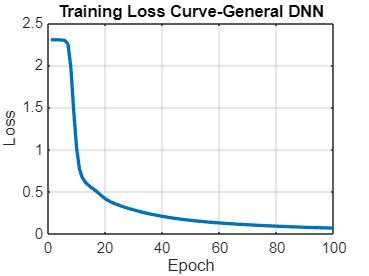

figure;
plot(loss_history, 'LineWidth', 2);
xlabel('Epoch');
ylabel('Loss');
title('Training Loss Curve-General DNN');
grid on;

Z1 = W1*X_test + b1;
A1 = max(0, Z1);
Z2 = W2*A1 + b2;
A2 = max(0, Z2);
Z3 = W3*A2 + b3;
[~, predictions] = max(Z3, [], 1);
predictions = predictions - 1;

accuracy = mean(predictions' == y_test) * 100;
fprintf('Test Accuracy for general DNN: %.2f%%\n', accuracy);

Test Accuracy for general DNN: 97.10%


conf_mat = confusionmat(y_test, predictions');

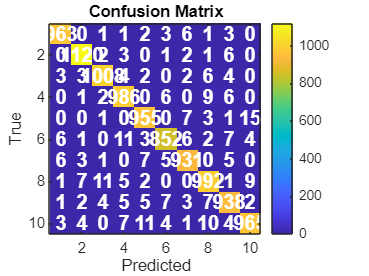

figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted');
ylabel('True');
title('Confusion Matrix');
axis square;

for i = 1:size(conf_mat,1)
    for j = 1:size(conf_mat,2)
        text(j, i, num2str(conf_mat(i,j)), ...
            'HorizontalAlignment','center', ...
            'Color','white', ...
            'FontSize',12, ...
            'FontWeight','bold');
    end
end

toc

Elapsed time is 172.093159 seconds.


# **Fashion- MNIST**

clearvars
tic
X_train = loadMNISTImages("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\Fashion-MNIST\train-images-idx3-ubyte");
y_train = loadMNISTLabels("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\Fashion-MNIST\train-labels-idx1-ubyte");
X_test  = loadMNISTImages("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\Fashion-MNIST\t10k-images-idx3-ubyte");
y_test  = loadMNISTLabels("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\eval_2\code\data\Fashion-MNIST\t10k-labels-idx1-ubyte");


Y_train = oneHotEncode(y_train, 10);
Y_test  = oneHotEncode(y_test, 10);

rng(1);
W1 = 0.01 * randn(128, 784);
b1 = zeros(128, 1);
W2 = 0.01 * randn(64, 128);
b2 = zeros(64, 1);
W3 = 0.01 * randn(10, 64);
b3 = zeros(10, 1);

epochs = 100;
batch_size = 128;
lr = 0.01;
num_samples = size(X_train, 2);
num_batches = floor(num_samples / batch_size);
loss_history = zeros(epochs, 1);

for epoch = 1:epochs
    perm = randperm(num_samples);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:, idx);
        Y = Y_train(:, idx);
        m = size(X,2);
        Z1 = W1*X + b1;
        A1 = max(0, Z1);
        Z2 = W2*A1 + b2;
        A2 = max(0, Z2);
        Z3 = W3*A2 + b3;
        Z3 = Z3 - max(Z3, [], 1);
        expZ = exp(Z3);
        Y_hat = expZ ./ sum(expZ,1);
        loss = -sum(sum(Y .* log(Y_hat))) / m;
        epoch_loss = epoch_loss + loss;
        dZ3 = Y_hat - Y;
        dW3 = (1/m) * dZ3 * A2';
        db3 = (1/m) * sum(dZ3,2);
        dA2 = W3' * dZ3;
        dZ2 = dA2 .* (Z2 > 0);
        dW2 = (1/m) * dZ2 * A1';
        db2 = (1/m) * sum(dZ2,2);
        dA1 = W2' * dZ2;
        dZ1 = dA1 .* (Z1 > 0);
        dW1 = (1/m) * dZ1 * X';
        db1 = (1/m) * sum(dZ1,2);
        W3 = W3 - lr*dW3;  b3 = b3 - lr*db3;
        W2 = W2 - lr*dW2;  b2 = b2 - lr*db2;
        W1 = W1 - lr*dW1;  b1 = b1 - lr*db1;
    end
    loss_history(epoch) = epoch_loss / num_batches;
    fprintf('Epoch %d/%d | Loss: %.4f\n', epoch, epochs, loss_history(epoch));
end

Epoch 1/100 | Loss: 2.3022
Epoch 2/100 | Loss: 2.3007
Epoch 3/100 | Loss: 2.2862
Epoch 4/100 | Loss: 1.9904
Epoch 5/100 | Loss: 1.3725
Epoch 6/100 | Loss: 1.1520
Epoch 7/100 | Loss: 1.0601
Epoch 8/100 | Loss: 0.9919
Epoch 9/100 | Loss: 0.9064
Epoch 10/100 | Loss: 0.8415
Epoch 11/100 | Loss: 0.8085
Epoch 12/100 | Loss: 0.7799
Epoch 13/100 | Loss: 0.7533
Epoch 14/100 | Loss: 0.7168
Epoch 15/100 | Loss: 0.6775
Epoch 16/100 | Loss: 0.6454
Epoch 17/100 | Loss: 0.6224
Epoch 18/100 | Loss: 0.6070
Epoch 19/100 | Loss: 0.5941
Epoch 20/100 | Loss: 0.5819
Epoch 21/100 | Loss: 0.5722
Epoch 22/100 | Loss: 0.5648
Epoch 23/100 | Loss: 0.5556
Epoch 24/100 | Loss: 0.5484
Epoch 25/100 | Loss: 0.5404
Epoch 26/100 | Loss: 0.5360
Epoch 27/100 | Loss: 0.5292
Epoch 28/100 | Loss: 0.5211
Epoch 29/100 | Loss: 0.5170
Epoch 30/100 | Loss: 0.5091
Epoch 31/100 | Loss: 0.5030
Epoch 32/100 | Loss: 0.4989
Epoch 33/100 | Loss: 0.4933
Epoch 34/100 | Loss: 0.4883
Epoch 35/100 | Loss: 0.4815
Epoch 36/100 | Loss: 0.4777
E

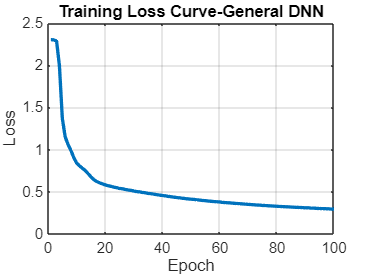

figure;
plot(loss_history, 'LineWidth', 2);
xlabel('Epoch');
ylabel('Loss');
title('Training Loss Curve-General DNN');
grid on;

Z1 = W1*X_test + b1;
A1 = max(0, Z1);
Z2 = W2*A1 + b2;
A2 = max(0, Z2);
Z3 = W3*A2 + b3;
[~, predictions] = max(Z3, [], 1);
predictions = predictions - 1;

accuracy = mean(predictions' == y_test) * 100;
fprintf('Test Accuracy for general DNN: %.2f%%\n', accuracy);

Test Accuracy for general DNN: 86.75%


conf_mat = confusionmat(y_test, predictions');

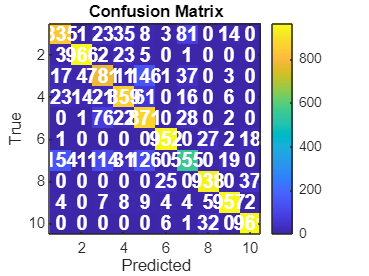

figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted');
ylabel('True');
title('Confusion Matrix');
axis square;

for i = 1:size(conf_mat,1)
    for j = 1:size(conf_mat,2)
        text(j, i, num2str(conf_mat(i,j)), ...
            'HorizontalAlignment','center', ...
            'Color','white', ...
            'FontSize',12, ...
            'FontWeight','bold');
    end
end

toc

Elapsed time is 203.144922 seconds.
